# Problem set #3

1. Option Pricing via FFT Techniques The Heston Model is defined by the following system of stochastic differential equations:


$$dS_t =rS_t \mathrm{dt}+\sqrt{\nu_t }S_t dW_t^1$$



$$d\nu_t =\kappa \left(\theta -\nu_t \right)\mathrm{dt}+\sigma \sqrt{\nu_t }dW_t^2$$
 


$$\mathrm{Cov}\left(dW_t^1 ,dW_t^2 \right)=\rho \mathrm{dt}$$


    The characteristic function for the Heston Model is known to be:


$$\omega \left(u\right)=\frac{\mathrm{exp}\left(\mathrm{iuln}S_0 +\mathrm{iu}\left(r-q\right)t+\frac{\kappa \theta t\left(\kappa -i\rho \sigma u\right)}{\sigma^2 }\right)}{{\left(\mathrm{cosh}\frac{\lambda t}{2}+\frac{\kappa -i\rho \sigma u}{\lambda }\mathrm{sinh}\frac{\lambda t}{2}\right)}^{\frac{2\kappa \theta }{\sigma^2 }} }$$



$$\Phi \left(u\right)=\omega \left(u\right)\mathrm{exp}\left(\frac{-\left(u^2 +\mathrm{iu}\right)\nu_0 }{\lambda \mathrm{coth}\frac{\lambda t}{2}+\kappa -i\rho \sigma u}\right)$$



$$\lambda =\sqrt{\sigma^2 \left(u^2 +\mathrm{iu}\right)+{\left(\kappa -i\rho \sigma u\right)}^2 }$$


    Assume the risk-free rate is 2%, the initial asset price is 250 and that the asset pays no dividends.

clear; clc;
rf = 0.02; s0 = 250;

**(a) Exploring FFT Technique Parameters** Consider a European Call Option with strike 250 expiring in six months. Additionally, assume you know that the parameters of the Heston Model are: σ = 0.2 ν0 = 0.08 κ = 0.7 ρ = −0.4 θ = 0.1

k = 250; t = 0.5;
sigma = 0.2; v0 = 0.08; kappa = 0.7; rho = -0.4; theta = 0.1;

    i. Calculate the price of the European Call option with many values for the damping factor, α. What values of α seem to lead to the most stable price?

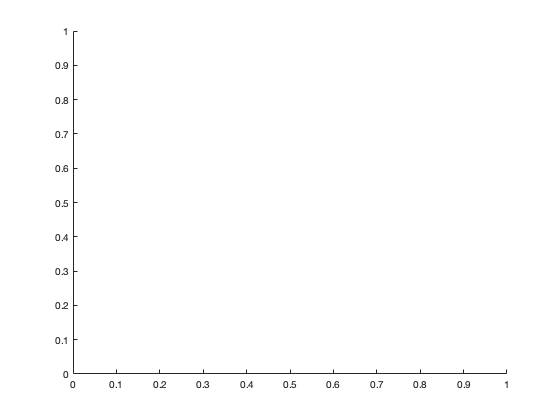

Not enough input arguments.

Error in myplot1 (line 18)
plot(X1,Y1,'DisplayName','1M');

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
aux.x0 = par.x0;
aux.N = 1024;
aux.K = k;
alpha_list = [.01, .25, .5, 1, 1.5, 5, 10, 20];
cfHes = @(u) cflib(u, t, par, 'Heston');

CHes = zeros(1, length(alpha_list));
for i = 1:length(alpha_list)
    aux.damp = alpha_list(i);
    CHes(i) = cf2call(cfHes,aux);
end
myplot1(CHes)

    when alpha is bigger than 0.25, option prices become stable. The values of alpha around 1 give the most stable price.

ii. Using the results above, choose a reasonable value of α and calculate the price of the same European Call with various values of N and ∆k (or equivalently N and B). Comment on what values seem to lead to the most accurate prices, and the efficiency of each parameterization.

clear aux
aux.x0 = par.x0; aux.damp = 1.5;
N_list = [16, 32, 64, 128, 256, 512];
C = cell(length(N_list),1);
K = cell(length(N_list),1);

for i = 1:length(N_list)
    aux.N = N_list(i);
    [C{i,1} K{i,1}] = cf2call(cfHes,aux);
end
myplot2(K{1}, C{1}, K{2}, C{2}, K{3}, C{3}, K{4}, C{4}, K{5}, C{5}, K{6}, C{6});

Error using myplot2
Too many input arguments.

B_list = [2, 4, 6, 8, 10, 12];
C = cell(length(N_list),1);
K = cell(length(N_list),1);

for i = 1:length(N_list)
    aux.uMax = B_list(i);
    [C{i,1} K{i,1}] = cf2call(cfHes,aux);
end
myplot2(K{1}, C{1}, K{2}, C{2}, K{3}, C{3}, K{4}, C{4}, K{5}, C{5}, K{6}, C{6});

    When N is bigger than 64 and B is bigger than 6, option prices become stable and accurate. The values of N around 256 and B around 10 give the most accurate prices. FFT algo's time complexity obeys O(NlogN), which means efficiency of parameterization is solely affected N, instead of B.

iii. Calculate the price of a European Call with strike 260 using various values of N and ∆k (or N and B). Do the same sets of values for N, B and ∆k produce the best results? Comment on any differences that arise.

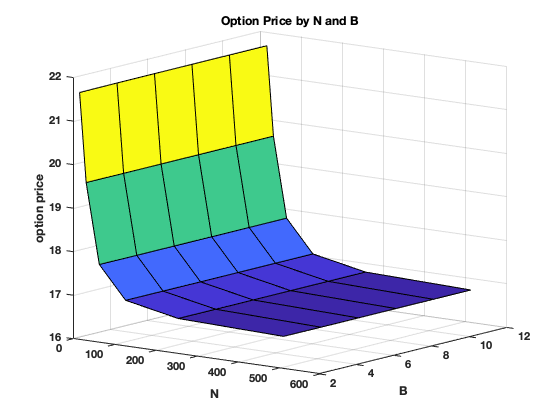

clear aux
aux.x0 = par.x0; aux.damp = 1.5;
aux.K = 260;
C = zeros(length(N_list), length(B_list));

for i = 1:length(N_list)
    for j = 1:length(B_list)
        aux.N = N_list(i);
        aux.uMax = B_list(j);
        C(i,j) = cf2call(cfHes,aux);
    end 
end
[X Y] = meshgrid(N_list, B_list);
myplot3(X, Y, C)

   Chosing a bigger N and B will give a better result. Regardless of computational effort, it's best to choose N and B to be as large as possible.

**(b) Exploring Heston Parameters** Assume the risk-free rate is 2.5%, the initial asset price is 150 and that the asset pays no dividends. σ = 0.4 ν0 = 0.09 κ = 0.5 ρ = 0.25 θ = 0.12

clear;
rf = 0.025; s0 = 150; sigma = 0.4; v0 = 0.09; 
kappa = 0.5; rho = 0.25; theta = 0.12;

i. Using these parameters, calculate Heston Model prices for three-month options at a range of strikes and extract the implied volatilities for each strike. Plot the implied volatility σ(K) as a function of strike.

t = 0.25;
par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
aux.x0 = par.x0;
cfHes = @(u) cflib(u, t, par, 'Heston');
[C K] = cf2call(cfHes,aux);
vol = blsimpv(s0, K, rf, t, C);
myplot4(K, vol, 'K')

'myplot4' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/xieyou/GitHub/MF796/hm3

Change the MATLAB current folder or add its folder to the MATLAB path.

ii. Use the FFT pricing technique to obtain prices of 150 strike calls at many expiries. Extract the implied volatility for each and plot the term structure of volatility by plotting time to expiry on the x-axis and implied volatility on the y-axis.

k = 150;
t_list = [0.25, 0.5, 0.75, 1, 1.25, 1.5, 1.75, 2];
aux.K = k;

C = zeros(length(t_list),1);
vol = zeros(length(t_list),1);
for i = 1:length(t_list)
    cfHes = @(u) cflib(u, t_list(i), par, 'Heston');
    C(i) = cf2call(cfHes,aux);
    vol(i) = blsimpv(s0, k, rf, t_list(i), C(i));
end

myplot4(t_list, vol, 'Tau')

'myplot4' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/xieyou/GitHub/MF796/hm3

Change the MATLAB current folder or add its folder to the MATLAB path.

iii. Holding all other parameters constant, vary each of the model parameters and plot the updated volatility skews and term structures. Comment on the impact that each parameter has on the skew and term structure.

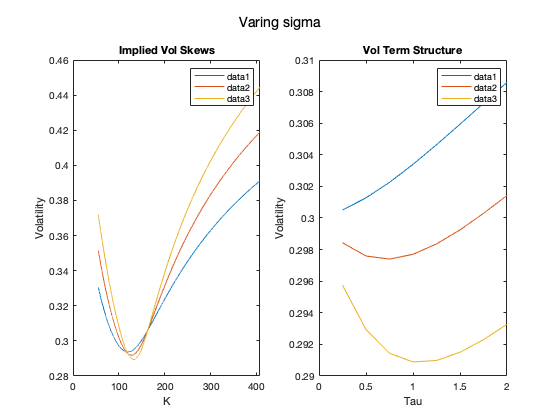

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
sigma_list = [0.3, 0.4, 0.5];
varying(sigma_list, 'sigma', par, t, t_list)

    As sigma increases, volatility surface becomes more steep. In other words, the extent of volatility smile becomes more severe. And volatility term structure falls down and becomes non-monotonic.

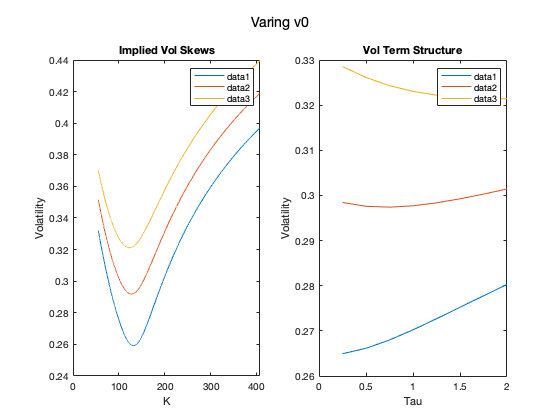

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
v0_list = [0.07, 0.09, 0.11];
varying(v0_list, 'v0', par, t, t_list)

    As v0 increases, volatility surface goes up to higher level. In other words, the extent of volatility smile remains basically the same. And volatility term structure goes up and becomes decreasing.

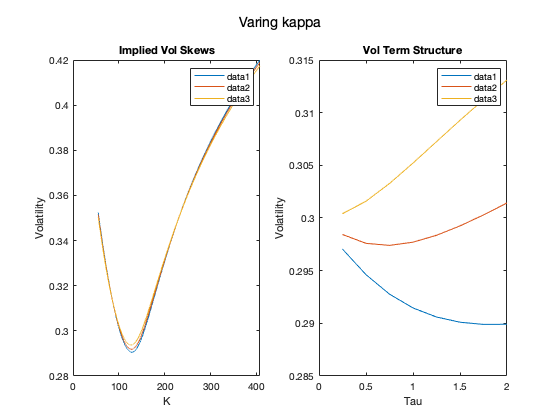

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
kappa_list = [0.3, 0.5, 0.8];
varying(kappa_list, 'kappa', par, t, t_list)

    As kappa increases, volatility surface remains basically the same. But volatility term structure goes up and becomes increasing.

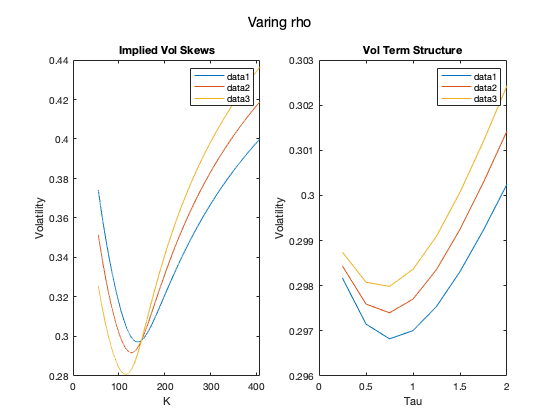

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
rho_list = [0.1, 0.25, 0.4];
varying(rho_list, 'rho', par, t, t_list)

    As rho increases, volatility surface shifts left and down. And volatility term structure goes up to higher level.

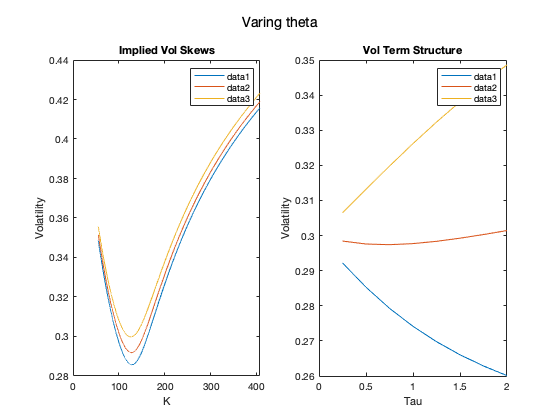

par = struct(...
    'rf', rf, 'q', 0, 'x0', log(s0), 'v0', v0, 'kappa', kappa, ...
    'theta', theta, 'sigma', sigma, 'rho', rho);
theta_list = [0.06, 0.12, 0.2];
varying(theta_list, 'theta', par, t, t_list)

    As theta increases, volatility surface goes up but not quite much. And volatility term structure goes up and becomes increasing.